# Transfer Function - Session 1 - 01

## Transfer Function 

Create the following trasfer function 


$$G\left(s\right)=\frac{10}{s^2 +3s+16}$$


num = 10;
den = [1 3 16];
sys1 = tf(num,den)

sys1 =
 
        10
  --------------
  s^2 + 3 s + 16
 
Continuous-time transfer function.
Model Properties


% add delay in transfer function 
sys1_d = tf(num,den,'ioDelay',5)

sys1_d =
 
                    10
  exp(-5*s) * --------------
              s^2 + 3 s + 16
 
Continuous-time transfer function.
Model Properties


Alternative way to define transfer function 

s = tf('s');   
sys2 = 10/(s^2+3*s+16)

sys1 =
 
        10
  --------------
  s^2 + 3 s + 16
 
Continuous-time transfer function.
Model Properties


## DC Motor Speed: System Modeling

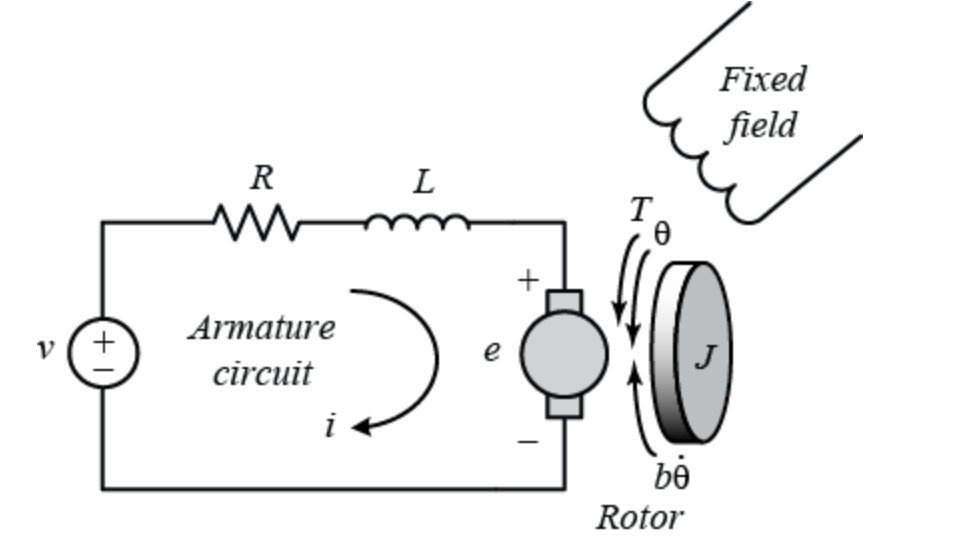

[DC Motor - TF](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling) 

`(J)     moment of inertia of the rotor     0.01 kg.m^2`

`(b)     motor viscous friction constant    0.1 N.m.s`

`(Ke)    electromotive force constant       0.01 V/rad/sec`

`(Kt)    motor torque constant              0.01 N.m/Amp`

`(R)     electric resistance                1 Ohm`

`(L)     electric inductance                0.5 H`

`K = Ke = Kt;`


$$G\left(s\right)=\frac{K}{\left(\textrm{Js}+b\right)\left(\textrm{Ls}+R\right)+K^2 }$$


J = 0.01;
b = 0.1;
K =0.01;
R = 1;
L = 0.5; 
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2)

P_motor =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


## `Pole - Zero Plot `

pole_system = pole(P_motor)

pole_system =    -9.9975
   -2.0025


zero_system = zero(P_motor)


zero_system =

  0×1 empty double column vector



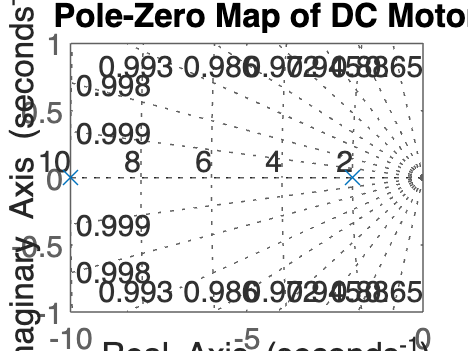

pzmap(P_motor);
title('Pole-Zero Map of DC Motor');
grid on;

## `Stability Analysis `

isstable(P_motor)

ans = logical
   1
